clear;
M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;
f = 0;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
C_ = C(2,:)

C_ =      0     0     1     0


D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];




x_0 = [0.01; 0.01; 0.01; 0.01];



%========LQR=======================
Q = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];
R = 1;
nu = 1;

[P1,~,Ky] = icare(A, B, Q, R, [], [], [], nu);

disp("Determinant of P1");

Determinant of P1


disp(det(P1));

   1.1701e+11




disp("P1");

P1


disp(P1);

   1.0e+06 *

    0.0000    0.0003   -0.0023   -0.0010
    0.0003    0.0069   -0.0549   -0.0230
   -0.0023   -0.0549    6.4074    2.6539
   -0.0010   -0.0230    2.6539    1.0992




K = - inv(R) * B' * P1;
disp("K");

K


disp(K);

   1.0e+03 *

    0.0010    0.0242   -5.5648   -2.3039



tspan = [0 90];

[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end

disp('phi');

phi


max_phi = max(x(:,3))

max_phi = 0.0105

min(x(:,3))

ans = -7.9494e-04

disp('a');

a


max_a = max(x(:,1))

max_a = 0.0345

min(x(:,1))

ans = -0.8129

disp('u');

u


max_u = max( u)

max_u = 2.2048

min(u)

ans = -78.4336

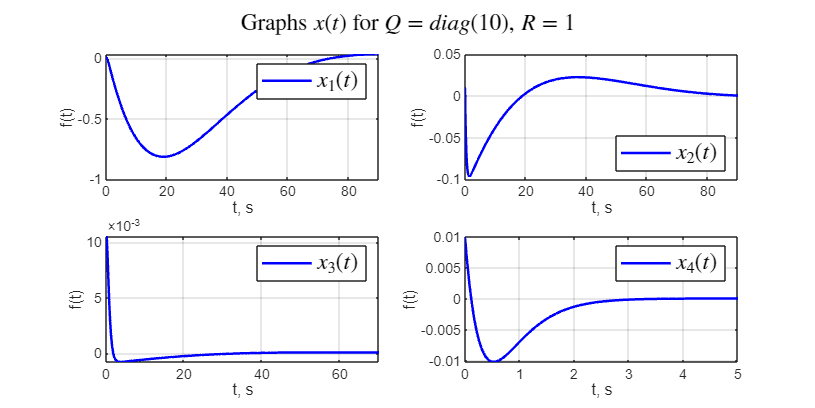



% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',1.5); 
legend('$x_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 90])
grid()

%figure('Position', [100 100 800 400])
subplot(2,2,2);
plot(t, x(:,2), 'b-', 'LineWidth',1.5); 
legend('$x_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 90])
grid()

subplot(2,2,3);
plot(t, x(:,3), 'b-', 'LineWidth',1.5); 
legend('$x_3 (t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 70])
grid()

subplot(2,2,4);
plot(t, x(:, 4), 'b-', 'LineWidth',1.5);
legend('$x_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 5])
grid()


sgtitle('Graphs $x(t)$ for $Q=diag(10)$, $R = 1$','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\6_lqr_n4.png'];
exportgraphics(gcf, full_path, 'Resolution', 300);